lines = readlines("ANON_19810211.GDT");
testing= false;
for c = 1:lines.size
    currentLine = lines(c);
    if currentLine.contains("Time") && currentLine.contains("Load")
        testing = true;
        testStart= c
    end
    if currentLine.contains("***") && testing== true
        testEnd = c
        testing = false;
    end
end

testStart = 110

testEnd = 214

for j=1:(testEnd-testStart)
    testLines(j,1)=lines(j+testStart-1);
end
testTable=zeros(13);
for i=1:testLines.size(1)
    splitLine=transpose(split(testLines(i)));
    lineLenght = splitLine.size;
    splitLine=cat(2,splitLine,zeros(1,(13-lineLenght(2))));
    testTable(i,:)= splitLine;
end
testTable(1,:)=[];
testTable(1,:)=[];
testTable(:,2)=[];
for j=1:size(testTable)
    if sum(testTable(j,:))==0
        testTable(j,:)=[];
    end
end
testTable(:,1)=transpose(0:10:1010);
testTable

testTable = 1.0e+03 *

         0       NaN         0         0         0         0         0         0         0         0         0         0
    0.0100         0    0.0780    0.0063    0.0046    0.0190    0.0280    0.0239    0.0327    0.0007    0.0081       NaN
    0.0200         0    0.0740    0.0047    0.0038    0.0180    0.0211    0.0326    0.0401    0.0008    0.0063       NaN
    0.0300         0    0.0740    0.0041    0.0035    0.0170    0.0212    0.0347    0.0409    0.0008    0.0056       NaN
    0.0400         0    0.0740    0.0029    0.0025    0.0130    0.0192    0.0363    0.0415    0.0009    0.0039       NaN
    0.0500         0    0.0740    0.0022    0.0019    0.0110    0.0190    0.0375    0.0435    0.0009    0.0030    0.0330
    0.0600       NaN         0         0         0         0         0         0         0         0         0         0
    0.0700         0    0.0760    0.0037    0.0029    0.0140    0.0202    0.0295    0.0378    0.0008    0.0049    0.0330
    0.080

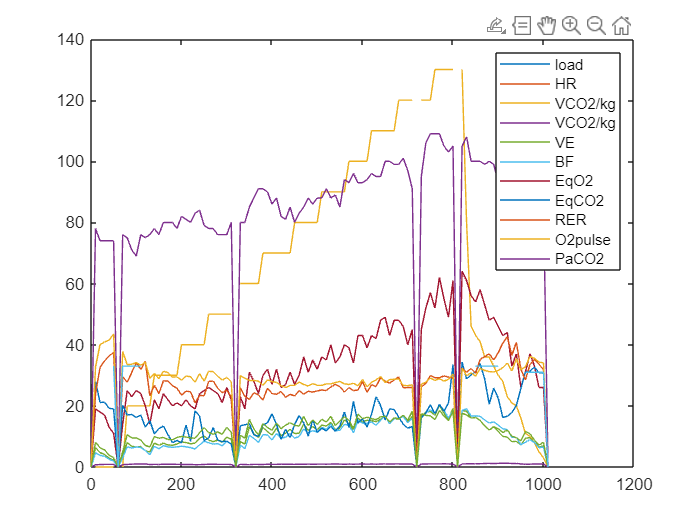


plot(testTable(:,1),testTable(:,2))
hold on
plot(testTable(:,1),testTable(:,3))
plot(testTable(:,1),testTable(:,4))
plot(testTable(:,1),testTable(:,5))
plot(testTable(:,1),testTable(:,6))
plot(testTable(:,1),testTable(:,7))
plot(testTable(:,1),testTable(:,8))
plot(testTable(:,1),testTable(:,9))
plot(testTable(:,1),testTable(:,10))
plot(testTable(:,1),testTable(:,11))
plot(testTable(:,1),testTable(:,12))
legend('load','HR','VCO2/kg','VCO2/kg','VE','BF','EqO2','EqCO2','RER','O2pulse','PaCO2')